clear
N_observation = 10;
n_subcarrier = 256;
freq_carrier = 3e9;
freq_IF = 2e7;
freq_shift = 500;
lambda = 3e8 / freq_carrier;
T_symbol = 1e-4;
N_sample = 8192; %8192
symbols_per_frame = 2;
pri = T_symbol*symbols_per_frame;
prf = 1 / pri;
freq_sampling = N_sample / T_symbol;
range_per_sampling_period = 3e8 * (1/freq_sampling) / 2;
rcs = 1;
Gt = 2936;
Gr = 2936;
Bn = (1/T_symbol)/symbols_per_frame;                        % BW post doppler
t = (linspace(0, T_symbol, n_subcarrier))';                 %symbol time
t2 = (linspace(0, T_symbol, N_sample))';                    %symbol time interpolated
pri_t = (linspace(0, pri, N_sample*symbols_per_frame))';    %pri time

## Wave Generator

%golay coding
golay_reg = golay(n_subcarrier);
golay_symbol_index = 1;
golay_code_value = golay_reg(golay_symbol_index, :);

%phase shifting
% alpha = deg2rad(90);
% deltat = -alpha ./ (2*pi*f);
% phase_shift = exp(1j * 2 * pi * f .* deltat);
% signal = golay_code_value .* phase_shift;

%ifft
iq_signal = ifft(golay_code_value, n_subcarrier)';

if N_sample > n_subcarrier
    a = 1:1:n_subcarrier;
    b = linspace(1, n_subcarrier, N_sample);
    iq_signal = interp1(a,iq_signal,b)';
end

% %offset-freq and IF Freq signal 
carrier = exp(-1i*2*pi*(freq_IF)*t2);
freq_shift = exp(-1i*2*pi*(freq_shift)*t2);
iq_signal = iq_signal .* carrier;
% iq_signal_shifted = iq_signal .* freq_shift;

%IQ modulator
tx_signal = (real(iq_signal) + imag(iq_signal));
% tx_signal_shifted = (real(iq_signal_shifted) + imag(iq_signal_shifted));

delay_lag = 128;
ref_signal = [tx_signal; zeros((N_sample*(symbols_per_frame-1)), 1)];
ref_iq_signal = [iq_signal; zeros((N_sample*(symbols_per_frame-1)), 1)];
zero_padded_signal = [tx_signal; zeros((N_sample*(symbols_per_frame-1)), 1)];
delayed_signal = circshift(zero_padded_signal, delay_lag);
if delay_lag > N_sample*(symbols_per_frame-1) && symbols_per_frame ~= 1
    delayed_signal(1:N_sample-1) = 0;
end


## Antenna & Channel Modelling

% waveform = phased.RectangularWaveform('SampleRate',freq_sampling,...
%     'PulseWidth',pri,'OutputFormat','Pulses',...
%     'N_observation',1,'PRF',prf); %1ms
target = phased.RadarTarget('Model','Nonfluctuating',...
    'MeanRCS',1,'OperatingFrequency',freq_carrier);
targetpos = phased.Platform('InitialPosition',[234.3750; 0; 0],...
    'Velocity',[100; 0; 0]);
antenna = phased.IsotropicAntennaElement(...
    'FrequencyRange',[5e8 5e9]);
transmitter = phased.Transmitter('PeakPower',5e3,'Gain',20,...
'InUseOutputPort',true);
transpos = phased.Platform('InitialPosition',[0;0;0],...
    'Velocity',[0;0;0]);
radiator = phased.Radiator('OperatingFrequency',freq_carrier,'Sensor',antenna);
collector = phased.Collector('OperatingFrequency',freq_carrier,'Sensor',antenna);
channel = phased.FreeSpace('SampleRate',freq_sampling,...
    'OperatingFrequency',freq_carrier,'TwoWayPropagation',false);

% waveform = phased.RectangularWaveform('SampleRate',5e6,...
%     'PulseWidth',6e-7,'OutputFormat','Pulses',...
%     'NumPulses',1,'PRF',1e4); %1ms
% target = phased.RadarTarget('Model','Nonfluctuating',...
%     'MeanRCS',1,'OperatingFrequency',1e9);
% targetpos = phased.Platform('InitialPosition',[1000; 1000; 0],...
%     'Velocity',[-100; -100; 0]);
% antenna = phased.IsotropicAntennaElement(...
%     'FrequencyRange',[5e8 5e9]);
% transmitter = phased.Transmitter('PeakPower',5e3,'Gain',20,...
% 'InUseOutputPort',true);
% transpos = phased.Platform('InitialPosition',[0;0;0],...
%     'Velocity',[0;0;0]);
% radiator = phased.Radiator('OperatingFrequency',1e9,'Sensor',antenna);
% collector = phased.Collector('OperatingFrequency',1e9,'Sensor',antenna);
% channel = phased.FreeSpace('SampleRate',waveform.SampleRate,...
%     'OperatingFrequency',1e9,'TwoWayPropagation',false);
% 
% receiver = phased.ReceiverPreamp('Gain',0,'LossFactor',0,...
%     'NoiseMethod','Noise power','NoisePower',1,...
%     'EnableInputPort',true,'SeedSource','Property','Seed',1e3);
receiver = phased.ReceiverPreamp('Gain',0,'LossFactor',0,...
    'SampleRate',freq_sampling,'NoiseFigure',5,...
    'EnableInputPort',false,'SeedSource','Property','Seed',1e3);

N_observation = 10;
sig = zero_padded_signal; % get waveform 
% sig = [[1 1 1 1] zeros(1,16380)]'
transpos = transpos.InitialPosition; % get transmitter position
rxsig = zeros(length(sig),N_observation);
% transmit and receive ten pulses
for n = 1:N_observation
    % update target position
    [tgtpos,tgtvel] = targetpos(pri);
    [tgtrng,tgtang] = rangeangle(tgtpos,transpos);
    tpos(n) = tgtrng;
    [txsig,txstatus] = transmitter(sig); % transmit waveform
    txsig1 = radiator(txsig,tgtang); % radiate waveform toward target
    txsig2 = channel(txsig1,transpos,tgtpos,[0;0;0],tgtvel); % propagate waveform to target
    txsig3 = target(txsig2); % reflect the signal
    % propagate waveform from the target to the transmiter
    txsig4 = channel(txsig3,tgtpos,transpos,tgtvel,[0;0;0]);
    txsig5 = collector(txsig4,tgtang); % collect signal
    rxsig(:,n) = receiver(txsig5); % receive the signal
end

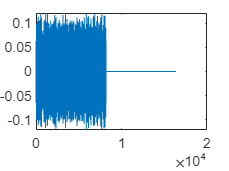

plot(sig)

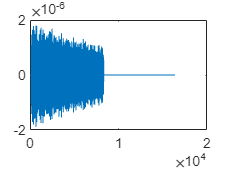

plot(real(txsig5))

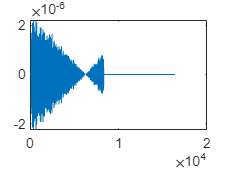

plot(imag(txsig5))

rxsig(100,:)

ans = 1.0e-05 *

  -0.0949 + 0.1003i  -0.0846 + 0.0385i  -0.0240 + 0.0312i  -0.0680 - 0.1636i   0.0809 - 0.0295i   0.0666 - 0.0359i   0.0246 + 0.0015i   0.0029 - 0.0367i  -0.0074 - 0.0650i   0.1116 - 0.0252i


rxsig(129,:)

ans = 1.0e-05 *

   0.1223 + 0.1414i   0.0768 - 0.0582i  -0.1439 + 0.0104i   0.2041 + 0.0312i  -0.0673 - 0.2147i  -0.1481 + 0.3037i   0.0695 - 0.1949i  -0.0289 + 0.0394i   0.0841 + 0.2079i  -0.0425 - 0.1671i


% plot(real(rxsig(:,10)))

% plot((imag(rxsig(:,10))))

% plot(real(txsig5) + imag(txsig5))

rx_signal = real(rxsig) + imag(rxsig);
[c,lags] = xcorr(rx_signal(:,1), ref_signal);

%range processing
size_lags =  size(lags, 2);
lags_abs = lags(1, round(size_lags/2):size_lags);
c_abs = (c(round(size_lags/2):size_lags, 1));

% rxy = c_abs/max(c_abs);
rxy = c_abs;
tau = lags_abs * T_symbol / max(lags_abs);
lag_of_max_c = lags_abs(c_abs == max(c_abs))

lag_of_max_c = 128

% phase_of_max_c = (lag_of_max_c / size(lags_abs, 2)) * 2 * pi;

lag_delay_time = (1/freq_sampling) * lag_of_max_c;
range_target = 3e8 * lag_delay_time / 2

range_target = 234.3750

% rxys_max = zeros(1, N_observation);
% rxys = zeros(N_sample*symbols_per_frame, N_observation);
% lags_detected = zeros(1, N_observation);
% rx_signal = real(rxsig) + imag(rxsig);
% 
% for i = 1:N_observation
%     %cross-correlation
%     [c,lags] = xcorr(rx_signal(:,i), ref_signal);
% 
%     %range processing
%     size_lags =  size(lags, 2);
%     lags_abs = lags(1, round(size_lags/2):size_lags);
%     c_abs = c(round(size_lags/2):size_lags, 1);
% 
%     % rxy = c_abs/max(c_abs);
%     rxy = c_abs;
%     tau = lags_abs * T_symbol / max(lags_abs);
%     lag_of_max_c = lags_abs(c_abs == max(c_abs))
%     % phase_of_max_c = (lag_of_max_c / size(lags_abs, 2)) * 2 * pi;
% 
%     lag_delay_time = (1/freq_sampling) * lag_of_max_c;
%     range_target = 3e8 * lag_delay_time / 2;
% 
%     lags_detected(:, i) = lag_of_max_c;
%     rxys(:, i) = c_abs; 
%     rxys_max(i) = max(c_abs);
% end

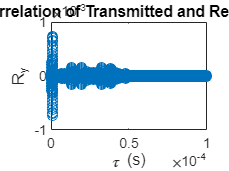

figure(4);
stem(tau, rxy);
xlabel('\tau (s)');
ylabel('R_x_y');
title('Cross Correlation of Transmitted and Received Signal');

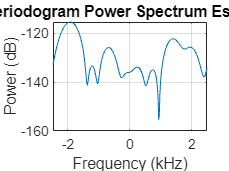

periodogram(rxsig(lag_of_max_c+1,:).',[],256,prf,'power','centered')

[Pxx,F] = periodogram(rxsig(lag_of_max_c+1,:).',[],256,prf,'power','centered');
[Y,I] = max(Pxx);
F(I)

ans = -1.9141e+03

tgtspeed = dop2speed(F(I)/2,lambda)

tgtspeed = -95.7031

% figure(1);
% plot(abs(rxsig(:,1)))
% figure(2);
% plot(abs(rxsig(:,2)))
% figure(3);
% plot(abs(rxsig(:,10)))

% prf = waveform.PRF;
% fs = waveform.SampleRate;
% fasttime = unigrid(0,1/freq_sampling,1/prf,'[)');
% rangebins = (physconst('LightSpeed')*fasttime)/2;

% probfa = 1e-9;
% NoiseBandwidth = 5e6/2;
% npower = noisepow(NoiseBandwidth,...
%     receiver.NoiseFigure,receiver.ReferenceTemperature);
% thresh = npwgnthresh(probfa,N_observation,'noncoherent');
% % thresh = sqrt(npower*db2pow(thresh));
% thresh = 1e-6;
% [pks,range_detect] = findpeaks(pulsint(rxsig,'noncoherent'),...
%     'MinPeakHeight',thresh,'SortStr','descend');
% range_estimate = rangebins(range_detect(1));

% ts = rxsig(range_detect(1),:).';
% ts_abs = real(ts) + imag(ts);
% ts_hilbert = hilbert(ts_abs);
% 
% [Pxx,F] = periodogram((ts_hilbert),[],256,prf,'centered');
% plot(F,10*log10(Pxx))
% grid
% xlabel('Frequency (kHz)')
% ylabel('Power (dB)')
% title('Periodogram Spectrum Estimate')

% [Y,I] = max(Pxx);
% lambda = physconst('LightSpeed')/1e9;
% tgtspeed = dop2speed(F(I)/2,lambda);
% fprintf('Estimated range of the target is %4.2f meters.\n',...
%     range_estimate)
% fprintf('Estimated target speed is %3.1f m/sec.\n',tgtspeed)
% if F(I)>0
%     fprintf('The target is approaching the radar.\n')
% else
%     fprintf('The target is moving away from the radar.\n')
% end